# Sys Course Project

Presentado por:

## Reset Simulation

clc
clearvars
close all
warning('off')

## Data Processing

Explain code here....

### Importing Data

data = importFile('dataSet.xlsx');
data_Colombia = data(data.countriesAndTerritories == 'Colombia',:);
data_Colombia = sortrows(data_Colombia,'dateRep','ascend');
data_Colombia = data_Colombia(data_Colombia.dateRep < '01-Jul-2020' | ismissing(data_Colombia.dateRep),:);
data_Colombia.cumulativeCases = cumsum(data_Colombia.cases);
data_Colombia.cumulativeDeaths = cumsum(data_Colombia.deaths);
timeFrame = datetime(data_Colombia.year,data_Colombia.month,data_Colombia.day);
timeFrame_test = 1:length(timeFrame);
cumulativeCases = data_Colombia.cumulativeCases;
cumulativeDeaths = data_Colombia.cumulativeDeaths;
totalCases = cumulativeDeaths + cumulativeCases;
data_Colombia.totalCases = totalCases

data_Colombia = 112×14 table
      dateRep      day    month    year    cases    deaths    countriesAndTerritories    geoId    countryterritoryCode    popData2018    continentExp    cumulativeCases    cumulativeDeaths    totalCases
    ___________    ___    _____    ____    _____    ______    _______________________    _____    ____________________    ___________    ____________    _______________    ________________    __________

    07-Mar-2020     7       3      2020      1        0              Colombia           

### Data Visualisation

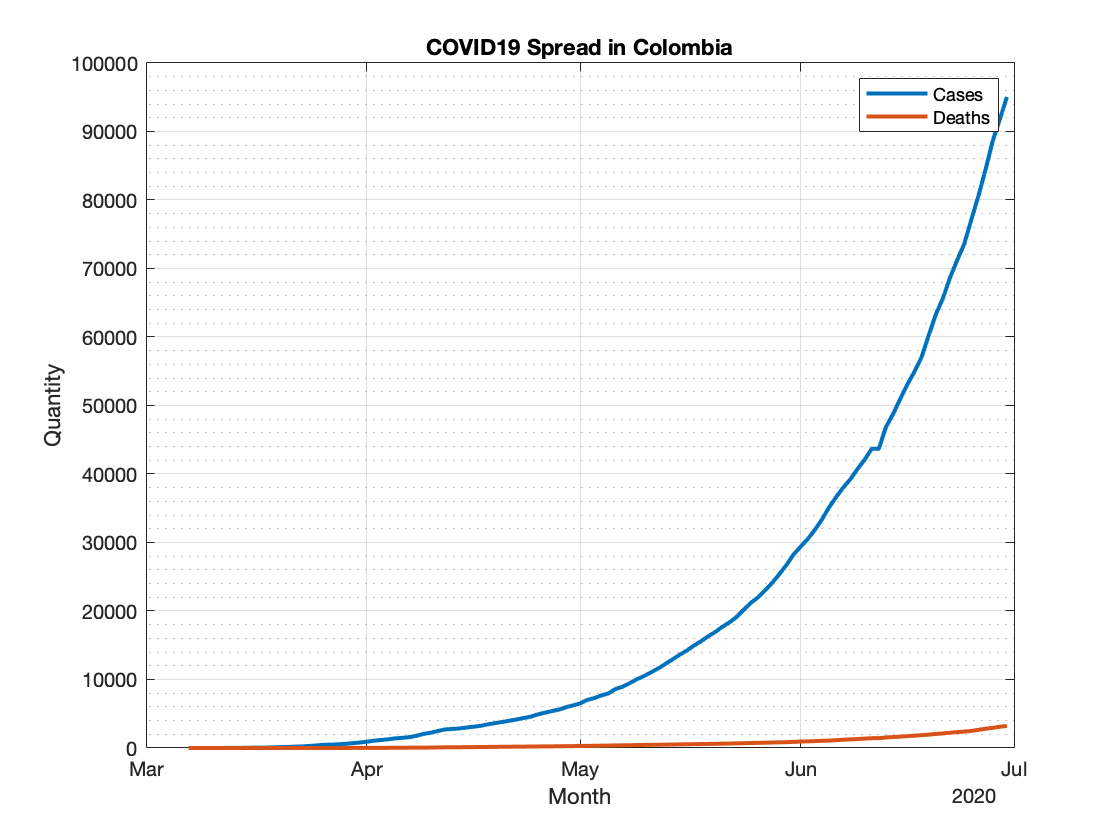

plot(timeFrame,cumulativeCases,timeFrame,cumulativeDeaths, 'LineWidth',2)
axis = gca; axis.YRuler.Exponent = 0;
xlabel('Month'), ylabel('Quantity'), title('COVID19 Spread in Colombia')
legend('Cases','Deaths')
grid on, grid minor

#### Fitting Curve to a Fifth Order Gaussian Model

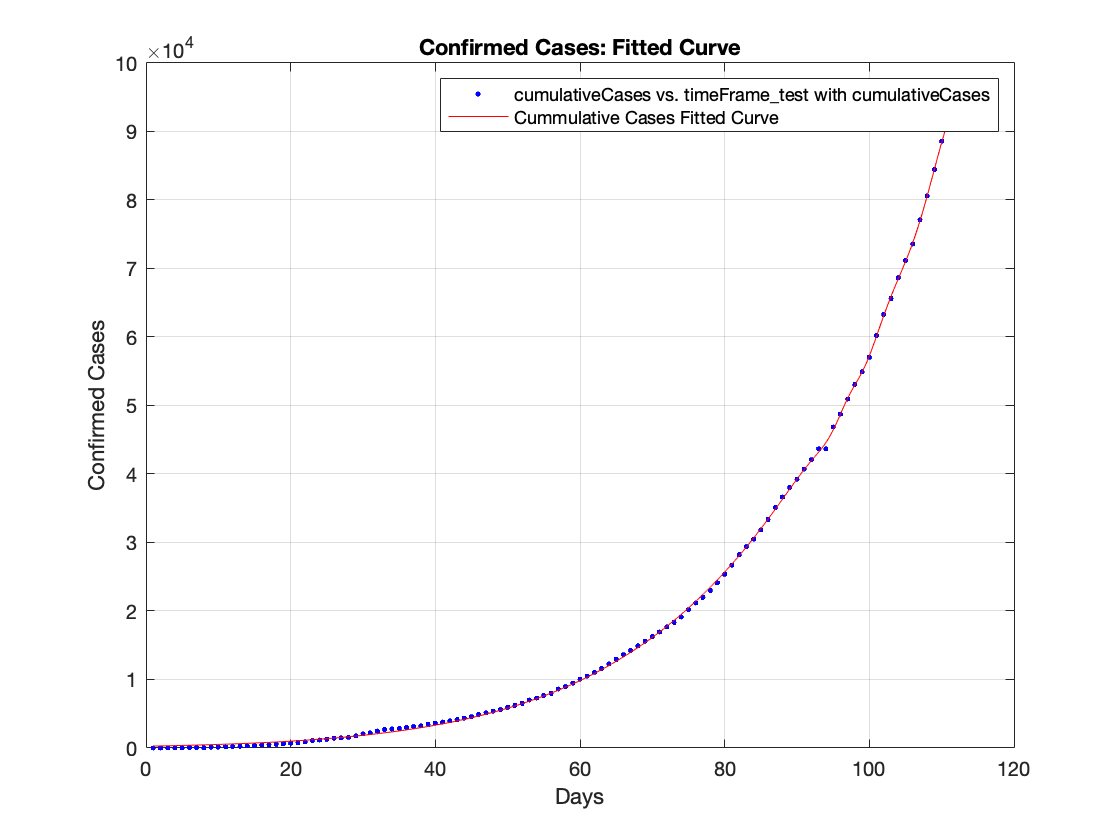

fittedCurve_cases = createFit(timeFrame_test, cumulativeCases);
xlabel('Days'), ylabel('Confirmed Cases'), title('Confirmed Cases: Fitted Curve')

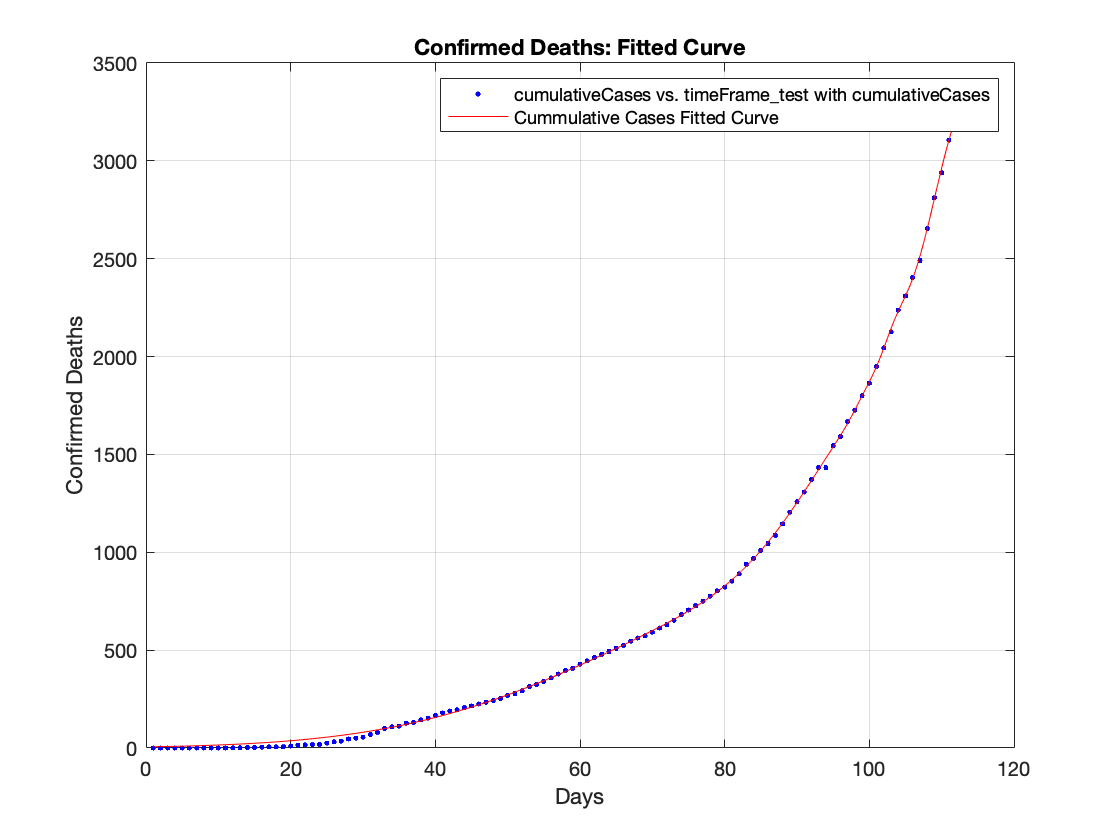

fittedCurve_deaths = createFit(timeFrame_test, cumulativeDeaths);
xlabel('Days'), ylabel('Confirmed Deaths'), title('Confirmed Deaths: Fitted Curve')

## Predicting Cure Stage

vaccineEffectiveness = 0.7;                                     % Number between 0.1 and 1
vaccineCost = 5;                                                % Vaccine cost in USD.
conversionRate = 3758.05;                                       % 1 USD to COP conversion ratio.
availableBudget = 10e9 / conversionRate                         % Available budget (in USD)

availableBudget = 2.6610e+06

availableDoses = floor(availableBudget/vaccineCost)             % Available Doses (Vaccine)

availableDoses = 532190

% PRUEBA